% x = 1:1:20
% y = []
% for i = 1:20
%     y(i) = (0.25)^(i-1)
% end
% for i=2:20
%     y(i) = y(i-1) + y(i)
% end
% exact_val = 1/(1-0.25)
% title("Archimedes")
% xlabel("term number")
% ylabel("sum of first x terms")
% legend("sum","exact val")
% plot(x,y,"b")
% hold on
% yline(exact_val, "r")
% hold off

Exercise 2:

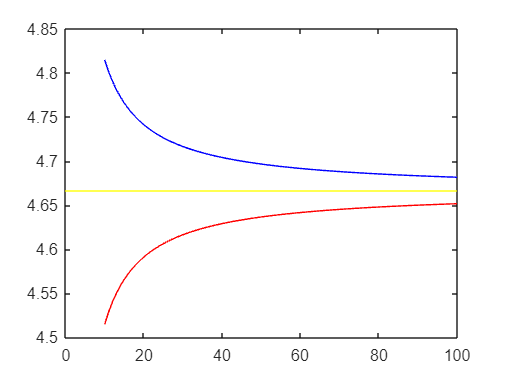

n = linspace(10,100,91);
lr_sum = [];
rr_sum = [];
for i = n
    dx = 3/i;
    temp_sum = [];
    temp_sum2 = [];
    for j=1:i
        temp_sum(j) = ((j-1)*dx+1)^0.5 * dx;
        temp_sum2(j) = ((j)*dx+1)^0.5 * dx;
    end
    lr_sum(i-9) = sum(temp_sum);
    rr_sum(i-9) = sum(temp_sum2);
end

plot(n,lr_sum,"r")
hold on
plot(n,rr_sum, "b")
yline(14/3,"y")